# Signal Detection Theory

**Signal Detection Theory (SDT)** explores how observers distinguish ambiguous stimuli, focusing on identifying a signal among noise. Observers respond "yes" or "no" to signal presence in experiments, leading to four outcomes: **hits** (correct signal detection), **correct rejections** (accurately identifying no signal), **misses** (overlooking a present signal), and f**alse alarms** (mistakenly perceiving a signal in noise). SDT provides a powerful tool to analyze cogntive perceptual and cogntive decisions.

Let's illustrate SDT with a toy psychophysics example. The task of the subject is to detect a specific auditory sound from background noise.

fs = 44100; % Sampling frequency in Hz
tnefreq = 1000; % Frequency of the tone
toneDuration = 0.01; % Duration of the tone in seconds
nTrials = 20; % Number of trials
t = 0:1/fs:toneDuration; % Time vector

% Generate tones
tone = sin(2*pi*tnefreq*t); 

results = zeros(1,nTrials); % Preallocate results array

trialSeq =([zeros(1,nTrials/2) ones(1,nTrials/2)]);
trialSeq = trialSeq(randperm(nTrials,nTrials));

%% Uncoment this loop to do the experiment
% for trial_i = 1:nTrials
% 
%     signal = tone + randn(1,length(tone)); % Signal itself is a bit noisy
%     noise = randn(1,length(tone));
%     % Randomly choose the sigal to play
%     if trialSeq(trial_i) == 1
%         sound(signal, fs);
%         correctAnswer = 1; % Signal
%     else
%         sound(noise, fs);
%         correctAnswer = 0; % Noise
%     end
%     
%     % Ask for user input
%     response = input('Was the tone  (1) or noise (0)? ');
%     
%     % Record the result: 1 for correct, 0 for incorrect
%     results(trial_i) = response;
%     
%     % Provide feedback or wait (optional)
%     pause(.5); % Wait for .5 second before the next trial
% end

To have a better understanding of how the subject performed the task we can computed following rates:

hitRate = sum(trialSeq & results)/sum(trialSeq)

hitRate = 0

falseAlarmRate = sum(~trialSeq & results)/sum(~trialSeq)

falseAlarmRate = 0

misseRate = sum(trialSeq & ~results)/sum(trialSeq)

misseRate = 1

correctRejectionRate = sum(~trialSeq & ~results)/sum(~trialSeq)

correctRejectionRate = 1

Assume that while the subject is doing the task we can record the activity of a single neuron in the auditory cortex, and we have recorded such activities for 1000 trials. Here comes the distributions of spike counts for two conditions: signal trials and noise tirals:

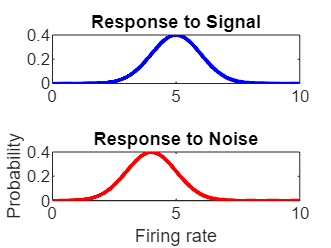

x = 0:0.01:10;
meanSignal = 5;
meanNoise = 4;

sigmaSignal = 1;
sigmaNoise = 1;

signalDist = normpdf(x,meanSignal,sigmaSignal);
noiseDist = normpdf(x,meanNoise,sigmaNoise);

figure
subplot(2,1,1)
plot(x,signalDist,'b', LineWidth=2)
title('Response to Signal')
subplot(2,1,2)
plot(x,noiseDist,'r', LineWidth=2)
title('Response to Noise')
xlabel('Firing rate')
ylabel('Probability')

Let's get back to the signal detection theory. Based on the neuronal response we want to predict the presentation of the signal. For such prediction we need a criterion.Let's say whenever the firing rate is bigger than 5 then the stimulus is present. What would be the hit, miss, false alarm and correct rejection rates in this scenario?

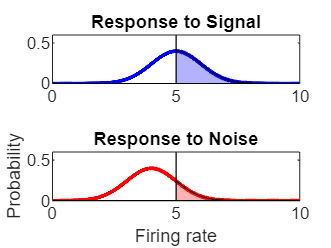

criterion = 5;
xShade = criterion:0.01:10;
yShadeSig = normpdf(xShade, meanSignal, sigmaSignal);
yShadeNoise = normpdf(xShade, meanNoise, sigmaNoise);



figure
subplot(2,1,1)
plot(x,signalDist,'b',LineWidth=2)
hold on
fill([xShade, 0], [0,yShadeSig], 'b', 'FaceAlpha', 0.3); % 'b' for blue, adjust 'FaceAlpha' for transparency
line([criterion criterion],[0 .6],'color','k')
title('Response to Signal')
subplot(2,1,2)
plot(x,noiseDist,'r',LineWidth=2)
hold on
fill([xShade, 0], [0, yShadeNoise], 'r', 'FaceAlpha', 0.3); % 'b' for blue, adjust 'FaceAlpha' for transparency
line([criterion criterion],[0 .6],'color','k')
title('Response to Noise')
xlabel('Firing rate')
ylabel('Probability')

The upper panel shows the distribution of firing rate when stimulus is present, the shaded area indicates hits and unshaded area indicates misses. In the lower panel which illustrates the distribution of firing rates in absence of stimulus the shaded area shows the false alarm and unshaded area show correct rejection. What is desireable is choosing a criterion that gives us highest possible hit rate (lowest misses) and lowest possible false alarm rate (highest correct rejections). Let's try different values for our criterion and plot flase alarm against hit.

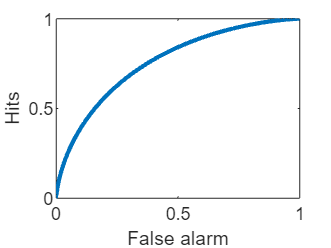

criterea = 0:.1:10;

for criterion_i = 1:length(criterea)
    hitRates(criterion_i) = 1 - normcdf(criterea(criterion_i),meanSignal,sigmaSignal);
    falseAlarms(criterion_i) =  1 - normcdf(criterea(criterion_i),meanNoise,sigmaNoise);
end
figure
plot(falseAlarms,hitRates,LineWidth=2)
xlabel('False alarm')
ylabel('Hits')

The desireable situation is when false alarm rate is 0 and false alarm is 1 (the closest point of the curve to upper left corner of the graph).

Let's explote another neuron which diffrentiates the two conditions in a more sensitive way.

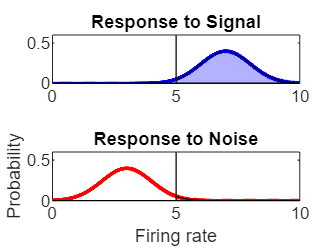

meanSignal = 7;
meanNoise = 3;

sigmaSignal = 1;
sigmaNoise = 1;

signalDist = normpdf(x,meanSignal,sigmaSignal);
noiseDist = normpdf(x,meanNoise,sigmaNoise);

criterion = 5;
xShade = criterion:0.01:10;
yShadeSig = normpdf(xShade, meanSignal, sigmaSignal);
yShadeNoise = normpdf(xShade, meanNoise, sigmaNoise);

figure
subplot(2,1,1)
plot(x,signalDist,'b',LineWidth=2)
hold on
fill([xShade, 0], [0,yShadeSig], 'b', 'FaceAlpha', 0.3); % 'b' for blue, adjust 'FaceAlpha' for transparency
line([criterion criterion],[0 .6],'color','k')
title('Response to Signal')
subplot(2,1,2)
plot(x,noiseDist,'r', LineWidth=2)
hold on
fill([xShade, 0], [0, yShadeNoise], 'r', 'FaceAlpha', 0.3); % 'b' for blue, adjust 'FaceAlpha' for transparency
line([criterion criterion],[0 .6],'color','k')
title('Response to Noise')
xlabel('Firing rate')
ylabel('Probability')

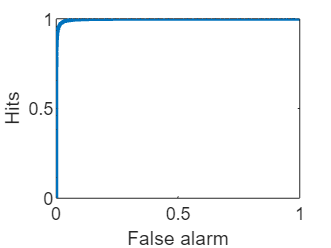


criterea = 0:.1:10;

for criterion_i = 1:length(criterea)
    hitRates(criterion_i) = 1 - normcdf(criterea(criterion_i),meanSignal,sigmaSignal);
    falseAlarms(criterion_i) =  1 - normcdf(criterea(criterion_i),meanNoise,sigmaNoise);
end
figure
plot(falseAlarms,hitRates,LineWidth=2)
xlabel('False alarm')
ylabel('Hits')

As it's obvisous the curve is closer to the upper left corner. We say this neuron discriminates the two condition with more sensitivity(higher rate) and specificity(less false alarm). Such curve is called Receiver Operatro Charactristics (ROC).

From these two neurons it is apparent that the ability to choose a good criterion to have high hit rate and low false alarm depends on how seperated the distributions are, in other words what is the difference between means of distributions. The bigger the difference, the easier to choose a criterion that maximizes hits and minimizes false alarm.

In these two examples we kept varience unchanged, but variance of the distribution also affect the discriminability between two conditions. The lower the variance the better discriminability.

We can define a measure that includes both important parameters here (mean and variance) to describe discriminability. We call this measure discriminability index or $d\prime$:


$$d' = \frac{\mu_s - \mu_n}{\sqrt{\frac{\sigma_s^2 + \sigma_n^2}{2}}}
$$


$d\prime$ quantify how well a signal can be distinguished from noise. $d\prime$determine how well you can set the criterion to optimize discriminability for example when $d\prime$is high you can make sure that by setting the criterion properly you can have a high hit rate and at the same time a low fale alarm.

**Likelihood **

Another useful concept in signal detection theory is likelihood ratio. It is a ratio of probabilities, that tells us how many times more likely the observed data is to occur under one hypothesis than under the other. For example our neuron's firing rate is 6 or larger we can compute the probability if it comes from signal distribution and also the probability if it comes from noise distribution. The ratio of these two probabilities is our likelihood and it indicates how seperated our signal and noise distributions are. 

**Likelihood Ratio in Signal Detection Theory**

A important concept in signal detection theory is the likelihood ratio. This ratio quantifies the strength of evidence in favor of one hypothesis over another. Specifically, it measures how many times more likely the observed data is to occur under the signal hypothesis compared to the noise hypothesis.

$LR = \frac{P(X|Signal)}{P(X|Noise)}

$�

*L**R* represents the likelihood ratio, *P*(*X*∣*S**i**g**na**l*) is the probability of observing the data *X* given that it originates from the signal distribution, and *P*(*X*∣*N**o**i**se*) is the probability of observing the data given that it originates from the noise distribution.

Come back to our neural response example. If the neuron's firing rate is 6 or higher, we can calculate the likelihood ratio by comparing two probabilities:

- The probability that this firing rate comes from the distribution when the signal is present.

- The probability that the same firing rate comes from the distribution when no signal is present (noise).

For instance, if *P*(*X*∣*S**i**g**na**l*)=0.2 and *P*(*X*∣*N**o**i**se*)=0.05, then the likelihood ratio *L**R*=0.2�/.05= 4. This tells us that the observed firing rate is four times more likely to occur under the signal condition than under the noise condition.

**Interpretation and Relation to d'**

A higher likelihood ratio indicates that the evidence strongly favors the signal hypothesis over the noise hypothesis, suggesting that the distributions of signal and noise are well separated. This concept is closely related to d' (d prime), a measure of sensitivity that quantifies the ability to distinguish between signal and noise. A higher likelihood ratio, indicating strong evidence for the signal, would correspond to a higher d', signifying better discriminability between signal and noise.

Visual Aids and Interpretation

Including a graph or visual representation can immensely aid in understanding. Imagine plotting two overlapping distributions: one for signal and one for noise. The area where they overlap is where decision-making becomes challenging. The likelihood ratio helps quantify this overlap and guides decision-making by indicating how much more likely one hypothesis is compared to the other.

In interpreting the likelihood ratio:

- LR close to 1: The evidence does not strongly favor one hypothesis over the other; decision-making is uncertain.

- High LR: Strong evidence in favor of the signal hypothesis; the observed data is much more likely under the signal condition.

- Low LR: Strong evidence in favor of the noise hypothesis; the observed data is more consistent with noise.